Source: [TI App Note: Why use a Gate Drive Transformer](https://www.ti.com/lit/pdf/SLLA602)

## Compute magnitization current needed to energize GDT primary inductance

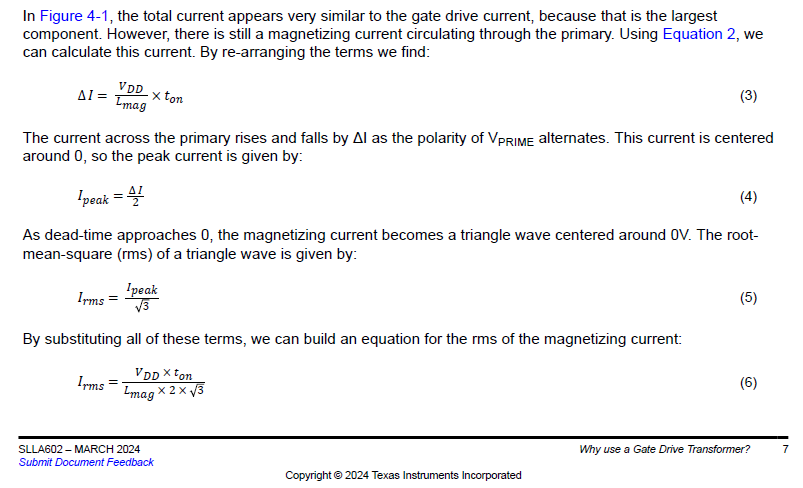

L_mag = L_GDT_pri;  

% Magnitization current circulating through primary
I_mag_delta = (V_gdt_drive/L_mag)*t_pri_max; % A

% Compute peak magnitization current
I_mag_peak = I_mag_delta/2; % A

% Compute rms current
I_mag_rms = I_mag_peak/sqrt(3);

#### Compute Vdroop

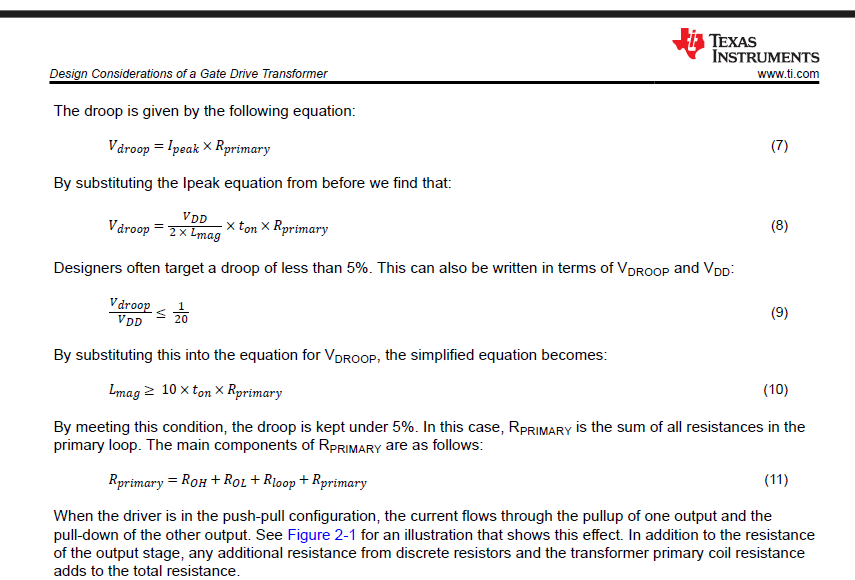

% Compute the total resistance in the GDT primary loop
R_gdt_pri_tot = R_gdt_drv_pu + R_gdt_drv_pd + L_GDT_pri_esr + R_ext_gdt_driver;
% Compute the voltage drop across the loop resistance
Vdroop_gdt_pri = I_mag_peak * R_gdt_pri_tot;

% Express droop in terms of percent
Vdroop_gdt_pri_percent = Vdroop_gdt_pri/V_gdt_drive;


## Compute Coupling Capacitor

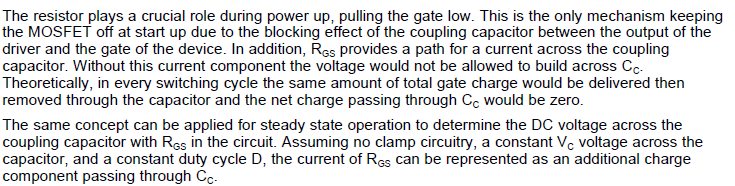

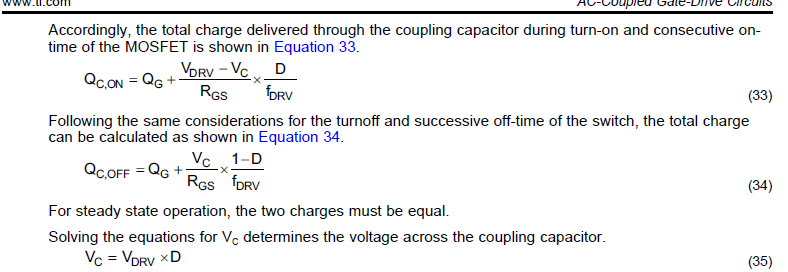

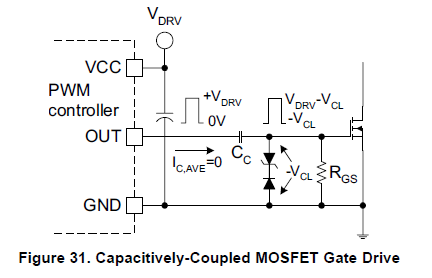

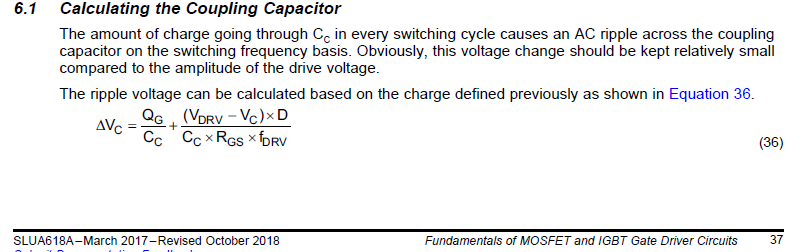

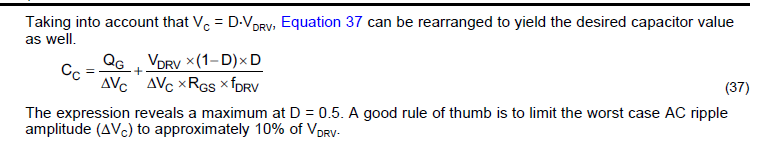

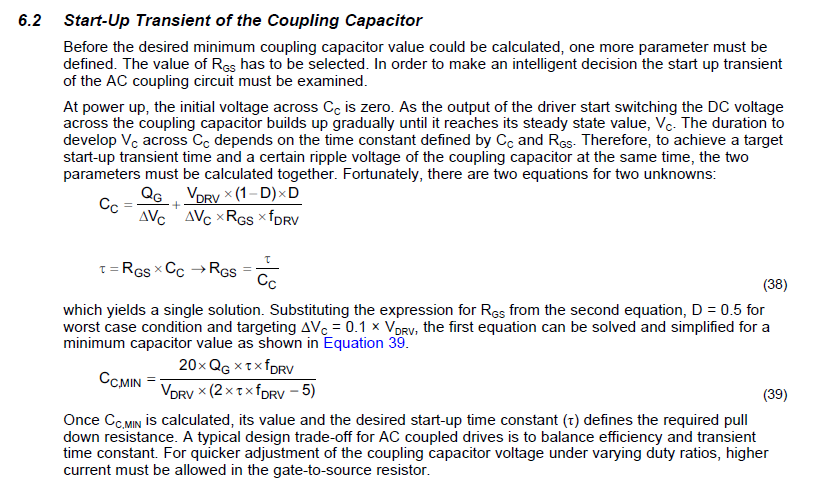

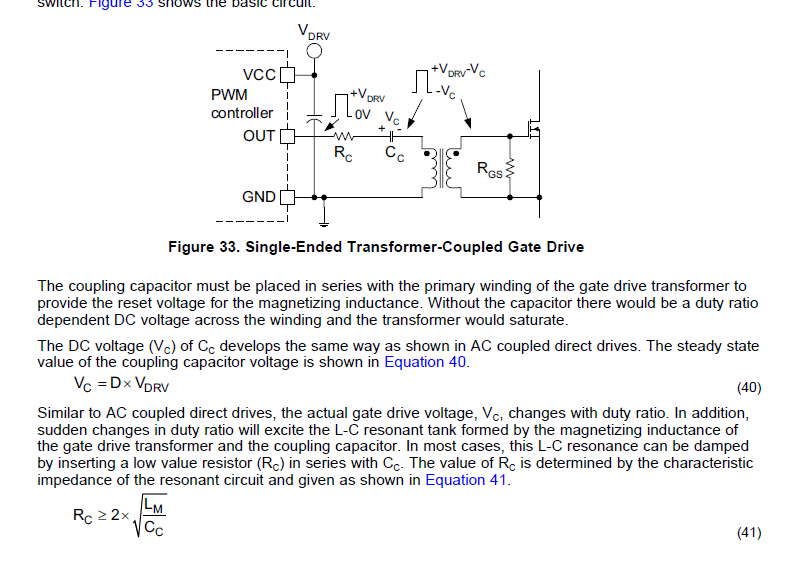

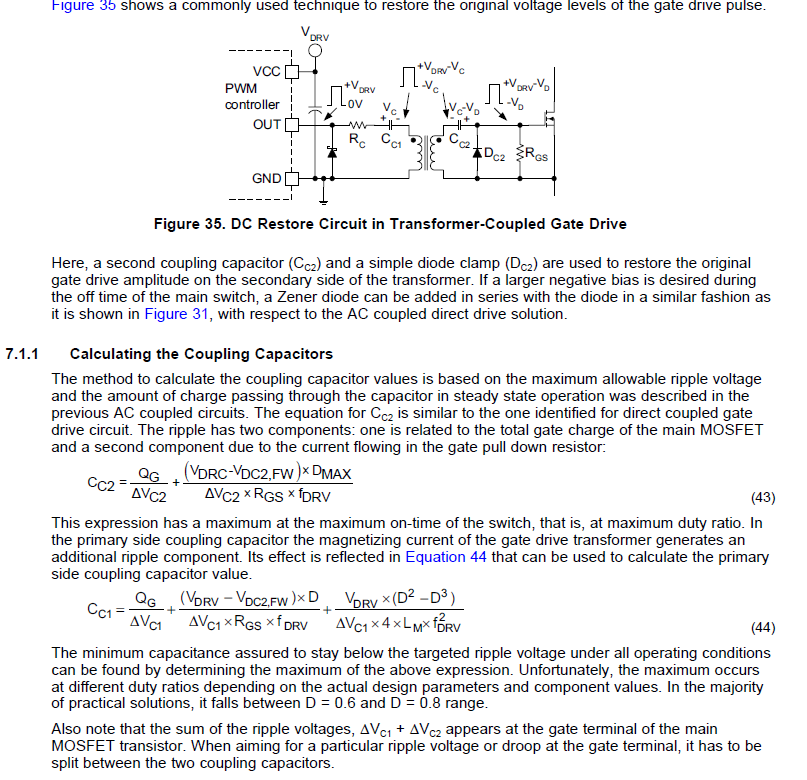

% Set coupling capacitor ripple voltage to be 10% of drive voltage as rule
% of thumb
V_c1_delta = 0.1 * V_gdt_drive;

if GDT_Driver_topology == "unipolar"
    % Pull-down resistor required on IGBT gate to sink charge
    % from gate capacitance to turn-off IGBT
    error("ERROR: Pull-down resistor not implemented!");
elseif  GDT_Driver_topology == "bipolar"
    % Pull-down resistor not required since driver can source AND sink
    % current, which sink the charge stored in the IGBT gate on the
    % secondary side causing it to turn off. This simplifies the bypass
    % equation seen above (eg.44, second term goes to 0 since Rgs = Inf)
    D = 0.5;    % duty cycle, always symmetrical
    % Recommended primary coupling capacitor, F
    Cc1_GDT_Driver = (IGBT.Q_g/V_c1_delta) + (V_gdt_drive*((D^2) - (D^3)))/(V_c1_delta*4*L_GDT_pri*(SYSTEM.F_res_pri^2));
    fprintf("Recommended GDT primary coupling capacitor: %0.4f uF\n\n",Cc1_GDT_Driver*1e6)
    % Ensure that total primary loop resistance is enough to damp the LC
    % oscillations from the magnitizing inductance of the GDT primary and
    % the coupling capacitor tank circuit in the event of changes in duty
    % ratio (e.g. start-up and shut-down, drift etc.)
    R_gdt_pri_tot_min = 2*sqrt(L_GDT_pri/Cc1_GDT_Driver);
    if R_gdt_pri_tot >= R_gdt_pri_tot_min
         fprintf("Total primary loop resistance sufficient for LC oscillation damping: %0.0f >= %0.0f Ohm\n\n",R_gdt_pri_tot,R_gdt_pri_tot_min);
    else
         warning("Total primary loop resistance insufficient for LC oscillation damping: %0.0f < %0.0f Ohm\n\n",R_gdt_pri_tot,R_gdt_pri_tot_min);
    end
end

#### Print Results


fprintf("\n\n################ GDT Driver Params BEGIN ##########################\n\n")
fprintf("Peak GDT primary magnitization current: %0.4f A\n\n",I_mag_peak)
fprintf("RMS GDT primary magnitization current: %0.4f A(rms)\n\n",I_mag_rms)
if Vdroop_gdt_pri_percent < Vdroop_gdt_pri_percent_target
    fprintf("GDT primary voltage droop percentage w/in tolerance: %0.2f %%\n\n",Vdroop_gdt_pri_percent*100)
else
     warning("GDT primary voltage droop percentage exceeds tolerance!: %0.2f %% (target: <= %0.2f %%)\n\n",Vdroop_gdt_pri_percent*100, Vdroop_gdt_pri_percent_target*100)
     % Compute minimum GDT primary inductance necessary to satisfy voltage
     % droop requirement at the current loop resistance total
     Lmag_min = (t_pri_max*R_gdt_pri_tot)/(Vdroop_gdt_pri_percent_target*2); % H
     warning("Decrease total primary loop resistance or ensure that GDT primary inductance is >= %0.4f mH\n\n",Lmag_min*1e3) ;  
end

fprintf("################ GDT Driver Params END ##########################\n\n")